%https://www.electrical4u.com/magnetic-reluctance/
clear
filename = 'ubv_desing_params_00.xlsx';
[NUM,TXT,RAW] = xlsread(filename);
PI = pi;
for i=1:size(RAW,1)
    eval(RAW(i,1) + " = " + RAW(i,2) + ";")
    eval("valve." + RAW(i,1) + " = " + RAW(i,1) + ";")
end
clearvars -except valve

## Modification

## Sealin Surface

do = 0.5;
r = 0.25;
R = 0.5 * do + r;
fun = @(x) 2*pi*(sqrt(r^2 - x.^2) + R).*sqrt(r^2./(r^2 - x.^2))

fun = function_handle with value:
    @(x)2*pi*(sqrt(r^2-x.^2)+R).*sqrt(r^2./(r^2-x.^2))


S = integral(fun,0,r)

S = 1.6264

Ao = pi * do^2 / 4

Ao = 0.1963

Ap = pi * R^2

Ap = 0.7854

20.5*S

ans = 33.3412

50*Ap

ans = 39.2699

## Magnetic Reluctance

rel_perm = 850

rel_perm = 850

air_perm = 1.25663753*1e-6

air_perm = 1.2566e-06

valve.perm = rel_perm * air_perm

valve = struct with fields:
                               rom: 0.5000
                         clearance: 0.1000
                           oring_d: 1.7800
            face_oring_gland_depth: 1.3400
      sealing_surface_t_face_oring: 3
           face_oring_groove_width: 2.1500
                   face_oring_dout: 12.8100
               oring_groove_radius: 0.2000
          radial_oring_gland_depth: 1.2900
         radial_oring_groove_width: 2.3500
                 radial_oring_dout: 20.7300
             magnetic_top_bottom_t: 3
                           shell_t: 1.5000
                       coil_wire_A: 0.0500
                       coil_wire_d: 0.2523
                            coil_h: 25
                          coil_din: 9
                         coil_dout: 30
                     coil_former_t: 1.5000
                coil_former_hole_d: 6
                   coil_former_din: 9
                  coil_former_dout: 30
                  coil_former_h_in: 25
                 coil_

airGapMR_ratio = 6.1078

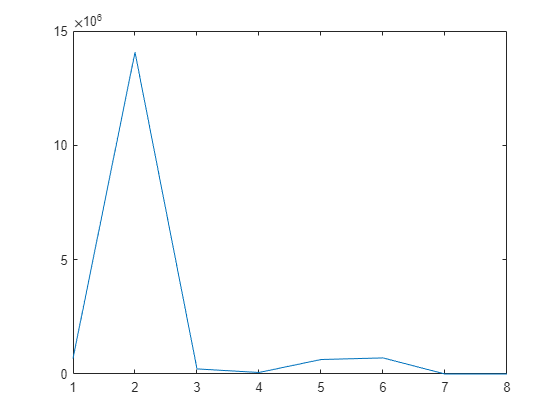

airGapMR_ratio = 6.1078

airGapMR_ratio = 6.1078

airGapMR_ratio = 6.1078

airGapMR_ratio = 6.1078

airGapMR_ratio = 6.1078

airGapMR_ratio = 6.1078

wire_areas = [0.0201 0.032 0.0509 0.0810 0.1288 0.2047 0.5176]; %mm^2
wire_gauge = [34 32 30 28 26 24 20];
rec_max_A = 3.5; % A/mm2;
for i=1:length(wire_areas)
    valve.wire_area = wire_areas(i);
    [Fmag(i),N(i),wire_len(i),wire_R(i),sol_V(i),sol_P(i),L(i)] = valve_magnetic_force(valve,valve.rom,rec_max_A * valve.wire_area,1);
end

Fmag

Fmag =    27.3215   27.3215   27.3215   27.3215   27.3215   27.3215   27.3215


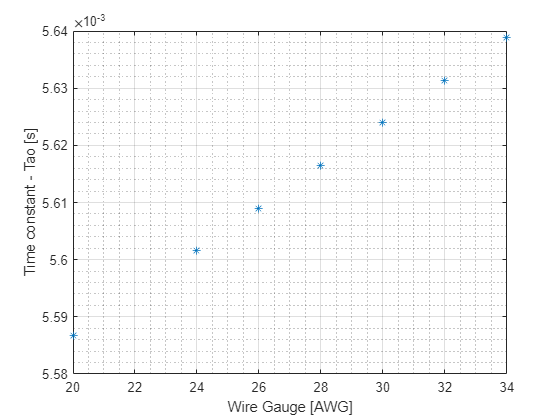

plot(wire_gauge,L./wire_R,'*'), xlabel('Wire Gauge [AWG]'), ylabel('Time constant - Tao [s]'), grid on, grid minor

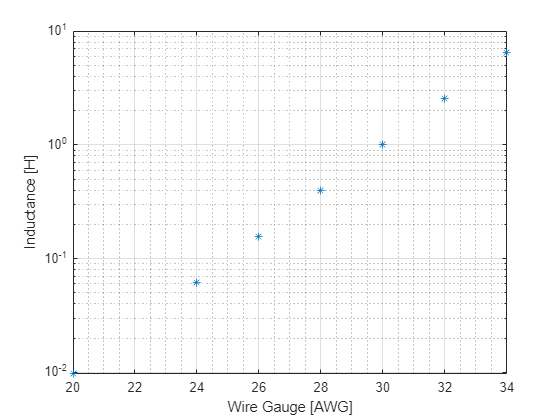

semilogy(wire_gauge,L,'*'), xlabel('Wire Gauge [AWG]'), ylabel('Inductance [H]'), grid on, grid minor

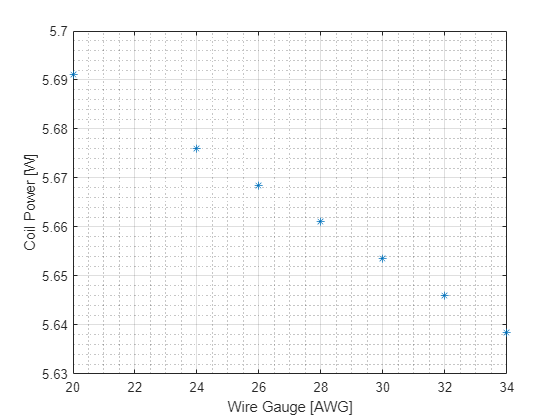

plot(wire_gauge,sol_P,'*'), xlabel('Wire Gauge [AWG]'), ylabel('Coil Power [W]'), grid on, grid minor

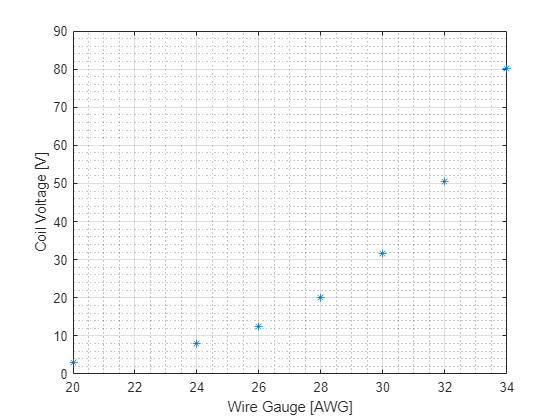

plot(wire_gauge,sol_V,'*'), xlabel('Wire Gauge [AWG]'), ylabel('Coil Voltage [V]'), grid on, grid minor

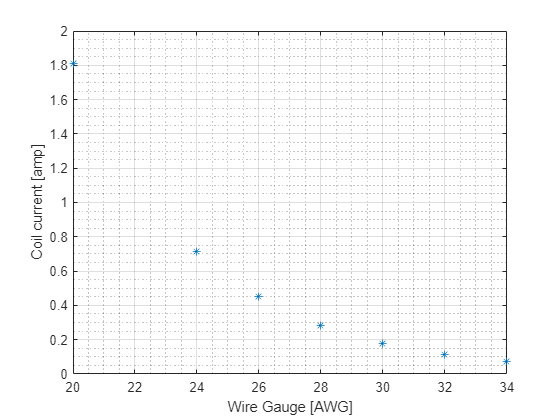

plot(wire_gauge,sol_P./sol_V,'*'), xlabel('Wire Gauge [AWG]'), ylabel('Coil current [amp]'), grid on, grid minor

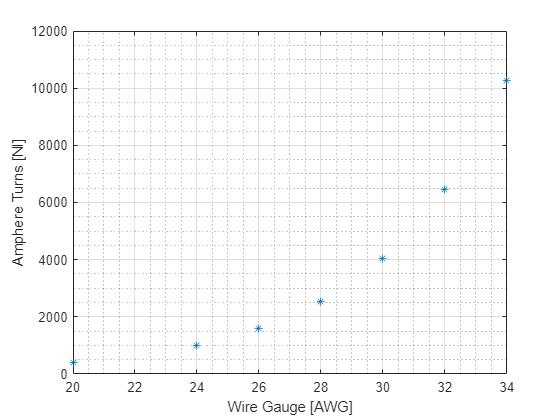

plot(wire_gauge,N,'*'), xlabel('Wire Gauge [AWG]'), ylabel('Amphere Turns [NI]'), grid on, grid minor

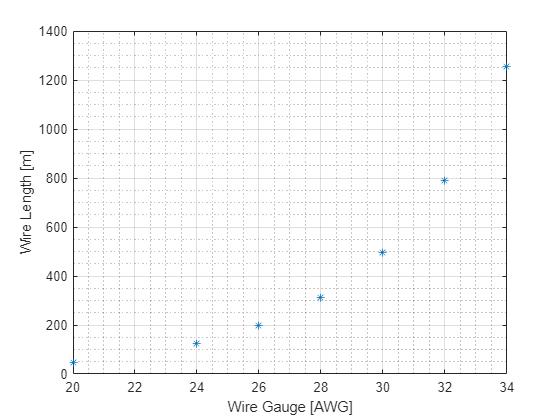

plot(wire_gauge,wire_len,'*'), xlabel('Wire Gauge [AWG]'), ylabel('Wire Length [m]'), grid on, grid minor

%plot(wire_areas,wire_R), xlabel('Wire cross section [mm^2]'), ylabel('Wire Resistance [Ohm]')

0.05 mm^2 = 30AWG wire.

## Dynamic model

% F = 0.5 * flux^2 / (Area * perm_air)
% N * i = R * flux
% L = N * flux / i
% V = L * di/dt + R * i
% tao = L / R
% V_L(t) = V * e ^ - t / tao
% I(t) = V / R * (1 - e ^ -t / tao)
wire_index = 4;
V = sol_V(wire_index) % source Voltage

V = 19.9683

dynamic.V = V;
R = wire_R(wire_index)

R = 70.4351

dynamic.R = R;
dt = 1e-6

dt = 1.0000e-06


tao = L(wire_index) / wire_R(wire_index)

tao = 0.0056

dynamic.tao = tao;
valve.wire_area = wire_areas(wire_index);
dynamic.valve = valve;

clearvars t V_L I Fmag sol_V sol_P L
V(1) = dynamic.V;
I(1) = 0;
[Fmag(1),N,wire_len,wire_R,sol_V(1),sol_P(1),L(1)] = valve_magnetic_force(valve,valve.rom,I(1));
t(1) = 0;
di_dt(1) = V(1) / L(1);
total_energy(1) = 0;
for i=2:ceil(5*tao/dt)
    t(i) = dt * (i-1) * 1e3;
    I(i) = I(i-1) + di_dt(i-1) * dt;
    applied_V = dynamic.V;
    if t(i) < 5
        applied_V = 5 * dynamic.V;
    end
    V_L(i) = applied_V - I(i) * dynamic.R;
    [Fmag(i),N,wire_len,wire_R,sol_V(i),sol_P(i),L(i)] = valve_magnetic_force(valve,valve.rom,I(i));
    di_dt(i) = V_L(i) / L(i) ;
    total_energy(i) = total_energy(i-1) + I(i)^2 * dynamic.R * dt;
end
I = I .* 1e3;
tao3index = ceil(3*tao/dt);
t(tao3index)

ans = 16.8490

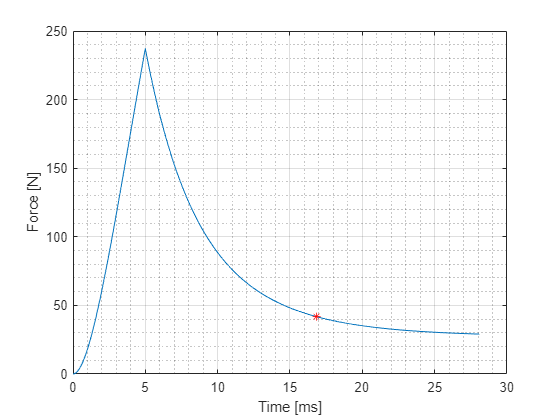

plot(t,Fmag,t(tao3index),Fmag(tao3index),'r*'), xlabel('Time [ms]'), ylabel('Force [N]'), grid on, grid minor

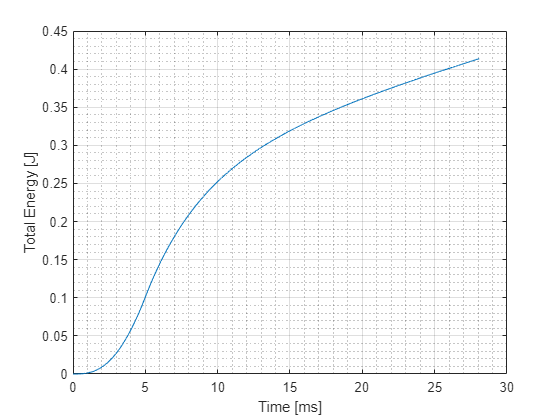

plot(t,total_energy), xlabel('Time [ms]'), ylabel('Total Energy [J]'), grid on, grid minor

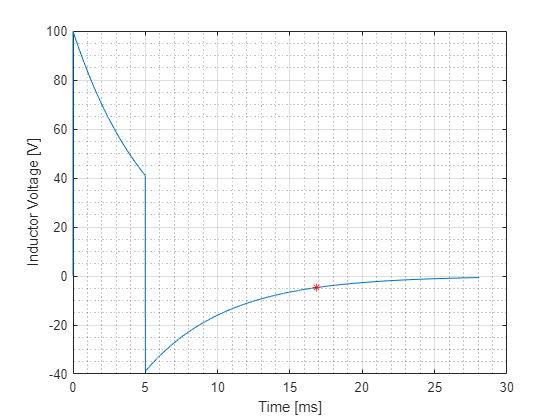

plot(t,V_L,t(tao3index),V_L(tao3index),'r*'), xlabel('Time [ms]'), ylabel('Inductor Voltage [V]'), grid on, grid minor

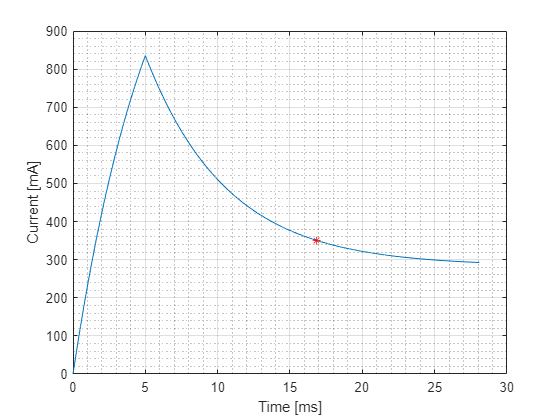

plot(t,I,t(tao3index),I(tao3index),'r*'), xlabel('Time [ms]'), ylabel('Current [mA]'), grid on, grid minor

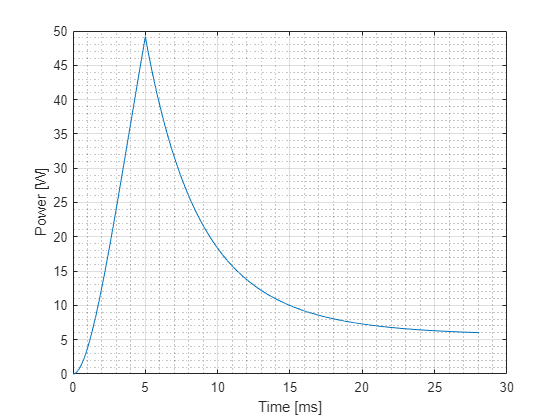

plot(t,sol_P), xlabel('Time [ms]'), ylabel('Power [W]'), grid on, grid minor

dynamic.valve_spool_m = 62 * 1e-3;

save 'ubv_electromagnetic' dynamic